# Optimize Stub Dimentions with Genetic Algorithm

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


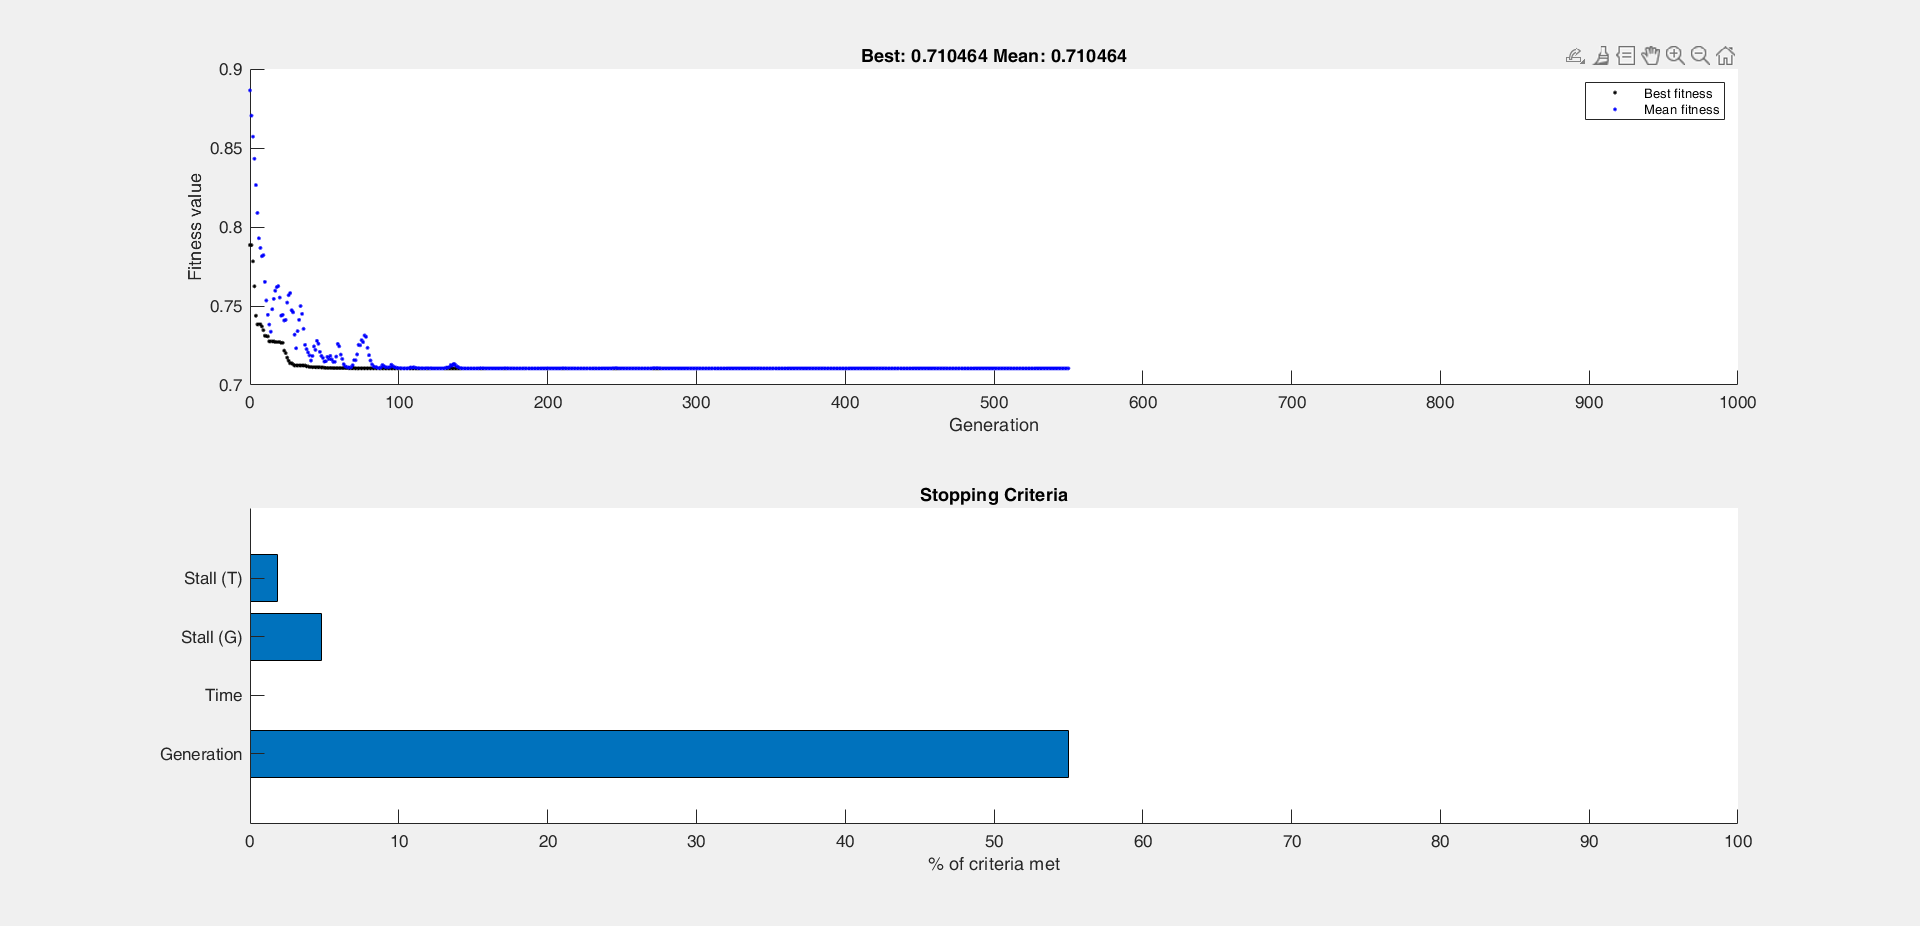

lb=[0 0.05 0.05 0 0 0];
ub=[1 1 1 1 1 1];

% Optimize
rng default
opts = optimoptions(@ga,'PlotFcn',{@gaplotbestf,@gaplotstopping});
opts = optimoptions(opts,'MaxGenerations',1000,'MaxStallGenerations', 500,'StallTimeLimit',200);
opts.PopulationSize = 200;
[x,Fval,exitFlag,Output]=ga(@stub,6,[],[],[],[],lb,ub,[],opts);


% Visualise the results
fprintf('The number of generations is: %d\n', Output.generations);

The number of generations is: 550


fprintf('The number of function evaluations is: %d\n', Output.funccount);

The number of function evaluations is: 104710


fprintf('The best function value found is: %g\n', Fval);

The best function value found is: 0.710464


x'

ans =     0.1886
    0.3771
    0.6350
    0.2206
    0.1998
    0.1865


function gamma_mean=stub(p)
% p=[d1 d2 d3 l1 l2 l3]
d1=p(1);
d2=p(2);
d3=p(3);
l1=p(4);
l2=p(5);
l3=p(6);
normf = (0.01:0.01:2)';

b=2*pi.*normf;

Z0=50;

ZL=200+150i; %load
Z1=zeta(ZL,b,d1); %TM with load

Zo1=zeta(0,b,l1);%open branch
Z2=parallel(Z1,Zo1);

Z3=zeta(Z2,b,d2);

Zo2=zeta(0,b,l2);%open branch
Z4=parallel(Z3,Zo2);

Z5=zeta(Z4,b,d3);

Zo3=zeta(0,b,l3);%open branch
Zin=parallel(Z5,Zo3);

gamma=abs( (Zin-Z0)./(Zin+Z0) );
gamma_mean=mean(gamma);

end

function z=zeta(ZL,b,l,Z0)
    if nargin<4
        Z0=50;
    end
    z=Z0*(ZL+1i*Z0.*tan(b.*l))./(Z0+1i*ZL.*tan(b.*l));
end

function zp=parallel(z1,z2)
    zp=1./((1./z1)+(1./z2));
end